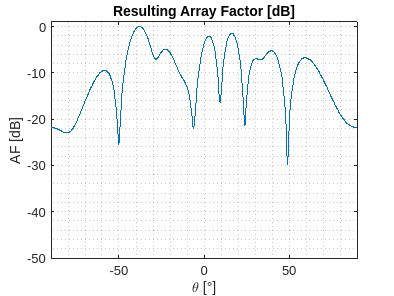

clear;
M = 12; 
angle_d = -40;
angle_i = 30; 
angle_i2 = 76; 
angle_i3 = -80;
angle_i4 = -5;
angle_i5 = 54;
angle_i6 = 0;
xs = exp(-1i*pi*(0:M-1)'*sin(angle_d*pi/180)); 
xi = exp(-1i*pi*(0:M-1)'*sin(angle_i*pi/180)); 
xi2 = exp(-1i*pi*(0:M-1)'*sin(angle_i2*pi/180));
xi3 = exp(-1i*pi*(0:M-1)'*sin(angle_i3*pi/180));
xi4 = exp(-1i*pi*(0:M-1)'*sin(angle_i4*pi/180));
xi5 = exp(-1i*pi*(0:M-1)'*sin(angle_i4*pi/180));
xi6 = exp(-1i*pi*(0:M-1)'*sin(angle_i4*pi/180));
AA(:,1) = xs; 
AA(:,2) = xi;
AA(:,3) = xi2;
AA(:,4) = xi3;
AA(:,5) = xi4;
AA(:,6) = xi4;
AA(:,7) = xi4;
b = zeros(7,1); 
b(1) = M; 

n_birds = 200;
j = 0;

lb = ones(M,1)*0 + 0i; % Lower bound
ub = ones(M,1)*1 + 1i; % Upper bound

% posizione attuale degli uccelli
pos_birds = (rand(n_birds,M)+ rand(n_birds, M)*1i).';
% posizioni migliori degli uccelli 
best_birds = pos_birds; 
speed = (rand(n_birds,M) + rand(n_birds, M)*1i).';

leader = (zeros(M,1) + zeros(M,1)*1i);

% miglior posizione globale (del leader)
f_lead=myfunc(leader, AA, b);

%%variabili aleatorie
alfa_i = 1; %rand(1);
alfa_s = 1; %rand(1);
csi = 0.9;
max_iter = 10000; 

%while(myfunc(leader, AA, b)-myfunc(old_leader, AA, b) > 1e-6 || j<1000)
for jj=1:max_iter
    for ii=1:n_birds
    
        f_bird = myfunc(pos_birds(:,ii), AA, b);
        % controllo se la nuova posizione è la migliore mai assunta 
        % dall'uccello i-esimo
        if(f_bird < myfunc(best_birds(:,ii), AA, b))
            best_birds(:,ii) = pos_birds(:,ii);
        end
    
        % controllo che la posizione sia la migliore glabalmente 
        if(f_bird < f_lead)
            f_lead = f_bird; 
            leader = pos_birds(:,ii); 
        end

        % aggiorno velocità e parametri 
        
        delta_i = alfa_i*rand(M,1).*(best_birds(:,ii) - pos_birds(:,ii));
        delta_s = alfa_s*rand(M,1).*(leader - pos_birds(:,1)); 
           
        speed(:,ii) = csi*speed(:,ii) + delta_i + delta_s; 
        pos_birds(:,ii) = pos_birds(:,ii) + speed(:,ii);
        pos_birds(:,ii) = max(pos_birds(:,ii), lb);
        pos_birds(:,ii) = min(pos_birds(:,ii), ub);
    end

    csi = csi - csi*0.0001;
end

theta = linspace(-90,90,1001);
AF = leader.'*exp(-1i.*pi.*(0:M-1)'*sind(theta));

figure;
plot(theta, 20.*log10(abs(AF)./max(abs(AF))));
grid minor; 
xlabel('\theta [°]')
ylabel('AF [dB]')
axis([-90 90 -50 1])
title('Resulting Array Factor [dB]')

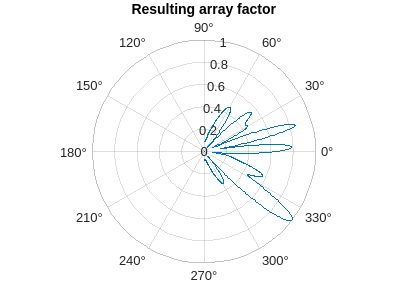


figure; 
polarplot(deg2rad(theta), abs(AF)./max(abs(AF)))
title('Resulting array factor')